## Tank Volume Selection Visualization

Tank_Names = ["220148-1",...
"2200153-1",...
"10070504-5",...
"10070504-2",...
"220062",...
"220150-1",...
"220149-1",...
"SH 90",...
"SH 98",...
"SH 38",...
"2 X 10070504-2",...
"3 X 10070504-2",...
"4 X 10070504-2",...
"2 X 220062",...
"2 X 220150-1",...
"2 X SH 90",...
"3 X SH 90",...
"2 X SH 98",...
"3 X SH 98",...
"3 X SH 38"];

m_f = [11.27049414,... %in lb
76.84427821,...
263.1726678,...
177.2517243,...
340.2303019,...
72.21021264,...
72.21021264,...
165.5052447,...
180.216822,...
83.85599066,...
354.5034486,...
531.7551728,...
709.0068971,...
680.4606038,...
144.4204253,...
331.0104894,...
496.5157342,...
360.4336441,...
540.6504661,...
251.567972];

Vol = [3.605162,... %in L
41.787105,...
149.0734487,...
100.4037617,...
308.3560607,...
31.2338126,...
31.2338126,...
90,...
98,...
38,...
200.8075234,...
301.2112851,...
401.6150468,...
616.7121214,...
62.4676252,...
180,...
270,...
196,...
294,...
114];

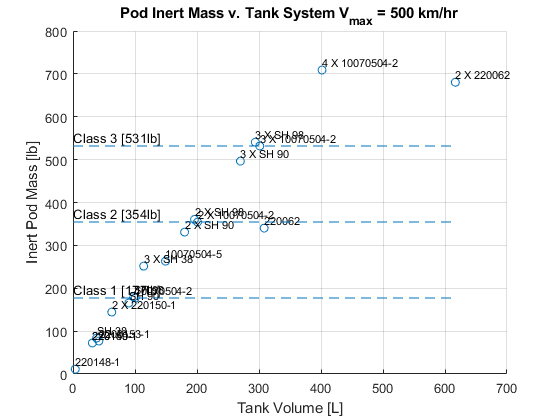

scatter(Vol,m_f)
grid on
text(Vol,m_f,Tank_Names,'FontSize',8,'horizontal','left', 'vertical','bottom')
%Add example class systems
Class_1 = 177.25; %177.25lb
line([0,max(Vol)],[Class_1,Class_1],'LineStyle','--')
text(0,Class_1,"Class 1 [177lb]",'vertical','bottom')

Class_2 = 354.503;%354.503
line([0,max(Vol)],[Class_2,Class_2],'LineStyle','--')
text(0,Class_2,"Class 2 [354lb]",'vertical','bottom')

Class_3 =531.755; %531.755
line([0,max(Vol)],[Class_3,Class_3],'LineStyle','--')
text(0,Class_3,"Class 3 [531lb]",'vertical','bottom')
xlabel('Tank Volume [L]')
ylabel('Inert Pod Mass [lb]')
title('Pod Inert Mass v. Tank System V_{max} = 500 km/hr')


%labels = Tank_Names